# Modal decomposition and analysis

## Setting up the system

Consider the following double [mass spring damper system](https://rotorlab.tamu.edu/Dynamics_and_Vibrations/Lectures%20(pdf)%20and%20homework/Particle%20Kinetics%202/L14-18.pdf)

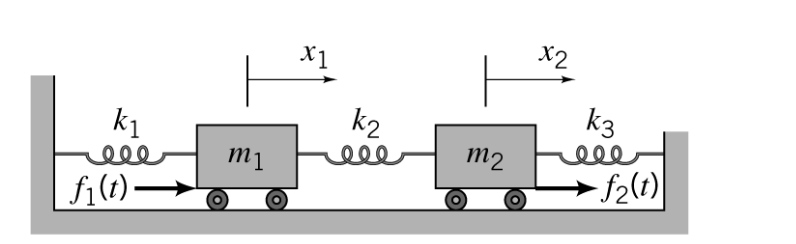

The euqations of motion for the above system can be shown to be (dampers are not shown above): 


$$
m_1 \ddot{x}_1 + (c_1 + c_2) \dot{x}_1 - c_2 \dot{x}_2 + (k_1 + k_2) x_1 - k_2 x_2 = f_1(t) \\
m_2 \ddot{x}_2 - c_2 \dot{x}_1 + (c_2 + c_3) \dot{x}_2 - k_2 x_1 + (k_2 + k_3) x_2 = f_2(t)

$$



$$\dot{\mathbf{x}} = A  \mathbf{x}  + B u$$


We will use the vector $\mathbf{x} = [x_1, \dot{x}_1, x_2, \dot{x}_2]$ as the state vector. We can use the above equations to create a state space object. For the the output equation, assume we are measuring the entire state, that is, $C$ will be an indentity matrix. 

%initializing parameters
m1 = 1; 
m2 = 1; 
k1 = 100; k2 = 100; k3 = 100; 
c1 = 2; c2 = 2; c3 = 2; 

%create the A,B,C and D matrices for the state space representation
A = [0,1,0,0; -(k1+k2)/m1, -(c1+c2)/m1, k2/m1,c2/m1; 0,0,0,1; k2/m2,c2/m2,-(k2+k3)/m2,-(c2+c3)/m2]

A =      0     1     0     0
  -200    -4   100     2
     0     0     0     1
   100     2  -200    -4


B = [0,0; 1/m1,0; 0,0; 0,1/m2]; 
C = eye(4); 
D = zeros(4,2); 

%create the state space object using the ss() function 
dmsdSS = ss(A,B,C,D);

%compute the poles of the systems 
pole(dmsdSS)

ans =   -3.0000 +17.0587i
  -3.0000 -17.0587i
  -1.0000 + 9.9499i
  -1.0000 - 9.9499i


## Modal decomposition

We can now analyse the system for a given aribitrary initial disturbance. However, instead of arbitrary disturbance, we will set the initial disturbance in the "direction" of a mode of the system, that is, we will set the initial state vector parallel to an eigenvector of the matrix $A$.  

%compute the eigenvectors of the matrix A using the eig() function 
[v,d] = eig(A);
v 

v =   -0.0071 - 0.0401i  -0.0071 + 0.0401i  -0.0070 - 0.0700i  -0.0070 + 0.0700i
   0.7059 + 0.0000i   0.7059 - 0.0000i   0.7036 + 0.0000i   0.7036 - 0.0000i
   0.0071 + 0.0401i   0.0071 - 0.0401i  -0.0070 - 0.0700i  -0.0070 + 0.0700i
  -0.7059 + 0.0000i  -0.7059 + 0.0000i   0.7036 + 0.0000i   0.7036 + 0.0000i


diag(d)

ans =   -3.0000 +17.0587i
  -3.0000 -17.0587i
  -1.0000 + 9.9499i
  -1.0000 - 9.9499i


**Reflect:**

- Are the eigenvectors complex? Considering that the state vector corresponds to position and veclocities of the masses, can these quantities be complex? 

- Is the sum of two eigenvectors corresonding to the same eignvalue of a matrix an eigenvector?

- Do the eigenvectors of $A$ occur in complex conjugates? Based on this observation, can you add two eigenvectors to create a real eigenvector? 

- Observe the eigenvalues of $A$. How do they relate to the poles of the system? What can you say about the stability of the system by computing the eigenvalues of $A$? 

**Enter your answers here: **

- Yes, the eigenvectors are complex. The position and vecloties of the masses cannot be complex. 

- Yes, the sum of two eigenvectors is an eigenvector. 

-     If $x$ is an eigenvector, then by definition, $Ax = \lambda x$. If $x_1$ and $x_2$ are eigenvectors, $A(x_1+x_2) = Ax_1 + Ax_2 = \lambda x_1 + \lambda x_2 = \lambda(x_1+ x_2)$

- Yes, add the two eigenvectors will produce an eigenvector which is real. 

-     $Ax_1 = \lambda_1x_1$ $Ax_1^* = \lambda_1^*  x_1^*$ $A(x_1 + x_1^*)  = \lambda_1x_1 + \lambda_1^* x_1^*  $($$x_1 = v_1$$, $x_1^* = v_2$)

-     If $x$ is in the span of $v_1$ and $v_2$, then $Ax$ will also be in the span of $v_1$ and $v_2$. 

- The eigenvalues of $A$ are identical to the poles of the system. 

## **Observing modes of the system**

We will now create an intitial state vector which is parallel to the sum of first two eigenvectors. Note that this means that out intial state is in the span of the first two eigenvectors. 

### Mode 1 

x0 = sum(v(:,1:2),2)

x0 =    -0.0141
    1.4119
    0.0141
   -1.4119


**Note: **x0 is not an eigenvector of $A$ but is in the span of $v_1$ and $v_2$. 

**Reflect: **

- What does the intial state vector correspond to physically. Are the masses moving towards each other or away? Are they moving with equal speeds? 

**Enter your answers here:**

- The masses are moving in the opposite direction with equal speeds. 

Let us now simulate the system with the above initial state vector for 2 seconds. 

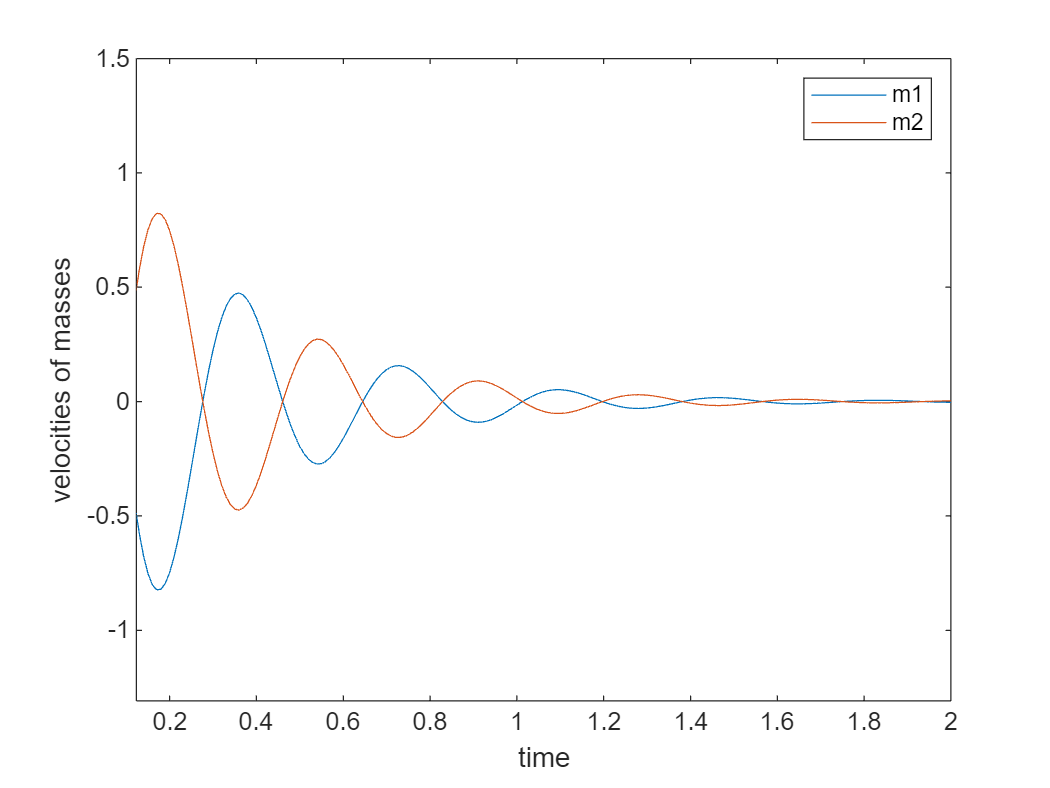

%write your code here to simulate the system for 2 seconds and plot the velocities of the two masses vs time.
t = (0:0.01:2)'; 
u = [0*t,0*t]; 
[y,tout] = lsim(dmsdSS,u,t,x0); 
plot(tout,y(:,[2,4]))
xlabel('time'); 
ylabel('velocities of masses'); 
legend('m1', 'm2')

Note: The initial state $x_0$ was in span of $v_1$ and $v_2$ (which are eigenvectors corresponding complex conjuage eigenvalues).  

Does the state of the system remain in the span of $v_1$ and $v_2$ for all time? We will see that the answer is yes. Therefore, we will call the span of $v_1$ and $v_2$ a 2-dimensional mode of the system. If the initial state is in this mode, then the system will be in this mode forever (assuming no external forces).  

a = y(175,:)

a =    -0.0004   -0.0012    0.0004    0.0012


c = v(1:2,1:2)\a(1:2)'

c =   -0.0009 - 0.0053i
  -0.0009 + 0.0053i


v1 = v(:,1); v2 = v(:,2); 
[a'  c(1)*v1+c(2)*v2]

ans =    -0.0004   -0.0004
   -0.0012   -0.0012
    0.0004    0.0004
    0.0012    0.0012


this means $a$ is in the span of $v_1$ and $v_2$ 

**Relfect:**

- By oberving the plot, describe the motion of the system in this mode. What patterns do you observe? 

- Measure the frequency of the signal from the plot. How does this frequency relate to the eigenvalues? 

- We added the first two eigenvectors to get a real initial state vector. In place of a simple addition, try other linear combinations (like v1+2*v2). What do you observe? How can you explain this behavior? 

**Enter your answers here: **

- The masses always move in opposite direction with equal speeds, just like the intial state. 

- The angular frequency ($$\omega$$) = 2*pi/(0.54-0.18) = 17.45 rad/sec, which is very close to the imaginary part of the first eigenvalue. Theoretically, they should be equal, so the discrepancy can be attributed to the measurement error. 

Definition of a mode: A mode is a subspace of the state space, such that, if the intial state is in this subspace, then the state of the system will always be in this subsapce. 

### Mode 2

Let's now observe the second mode of the system. We will obtain this by adding the third and the fourth eigenvectors. 

x0 = sum(v(:,3:4),2)

x0 =    -0.0141
    1.4072
   -0.0141
    1.4072


**Reflect: **

- What does the intial state vector correspond to physically. Are the masses moving towards each other or away? Are they moving with equal speeds? 

**Enter your answers here:**

- The masses are moving with equal velocities. 

Let us now simulate the system with the above initial state vector for 2 seconds. 

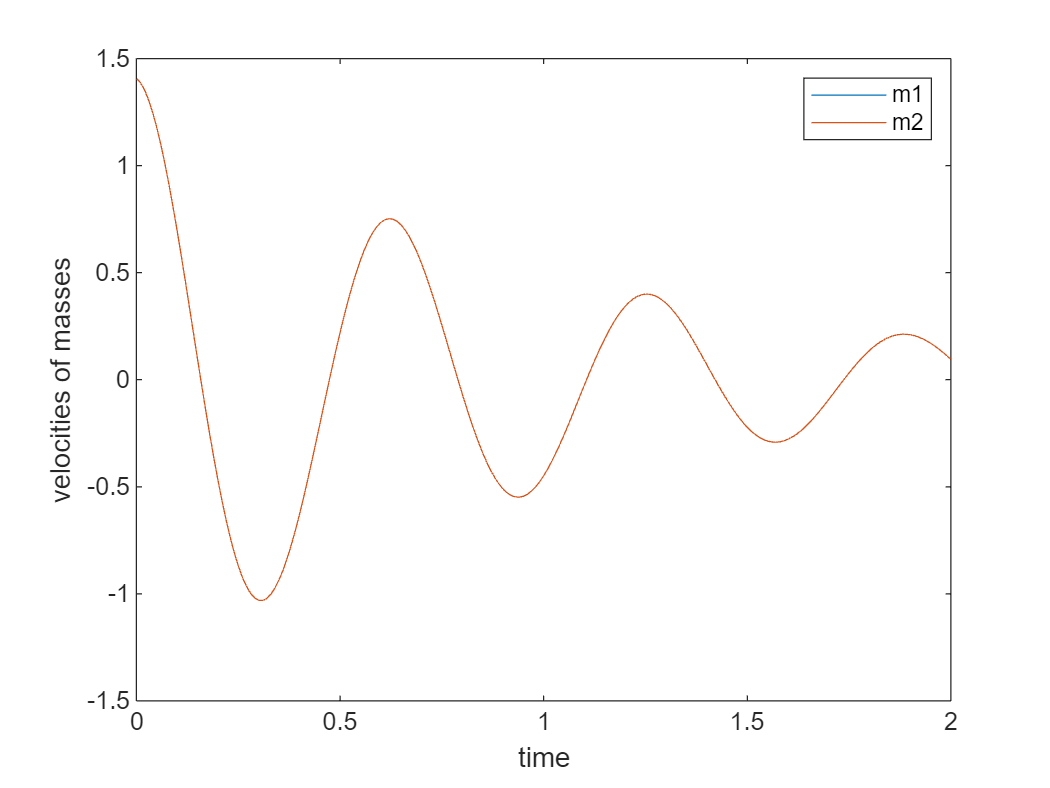

%write your code here to simulate the system for 2 seconds and plot the velocities of the two masses vs time.
t = (0:0.01:2)'; 
u = [0*t,0*t]; 
[y,tout] = lsim(dmsdSS,u,t,x0); 
plot(tout,y(:,[2,4]))
xlabel('time'); 
ylabel('velocities of masses'); 
legend('m1', 'm2')

You can verify that the state of the system will always be in the span of $v_3$ and $v_4$. Physically, this means that the masses will always have the same velocities. We can also say that the system remains in the second mode if it starts in this mode. 

**Relfect:**

- By oberving the plot, describe the motion of the system in this mode. What patterns do you observe? 

**Enter your answers here: **

- The masses are moving with equal velocities, just as the intial state. 

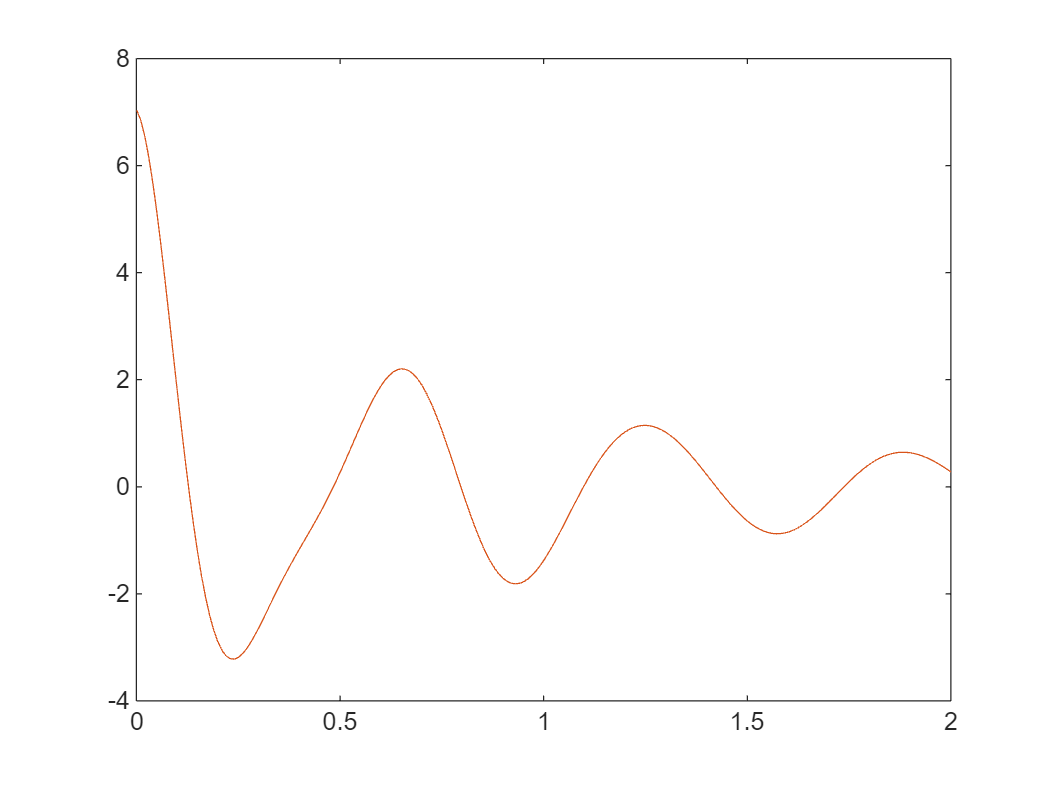

x01 = sum(v(:,1:2),2); %x01 is in mode 1, span of v1 and v2
x02 = sum(v(:,3:4),2); %x02 is in mode 2, span of v3 and v4
x0 = 2*x01 + 3*x02; %x0 is not in any mode 
t = (0:0.01:2)'; 
u = [0*t,0*t]; 
[y,tout] = lsim(dmsdSS,u,t,x0); 
[y1,tout1] = lsim(dmsdSS,u,t,x01);
[y2,tout2] = lsim(dmsdSS,u,t,x02);
plot(tout, y(:,2), tout1, 2*y1(:,2)+3*y2(:,2));

### Modal state representation (Modal form)

In the above sections, the state vector comprised of the position and velocities of the masses. When this is the case $$\ddot{x}_1$$,and $$\ddot{x}_2$$  depend on all other states. This makes the system appear complex and difficult to control, that is, the behavior of some states depend on all other states making it difficult to analyze. We can use numerical simulators, but that doesn't provide insight into how to control the system.

However, as we will see below, it is possible to define states in such a way that the system appears less complex. This way of representation the state space of the sytem is called the modal state represenation.

- In what we saw above, we can consider the positions and velocities of the masses as different coordinate axes representing a four dimensional space and the state vector is a coordinate point in this space. 

- If instead of using positions and velocities as axes, we can consider the eigenvectors of $A$ as coordiante axes, and represent the state vector as a coordinate point in terms of these axes. 

MATLAB provides a function `modalreal() `which makes this conversion for us. Let's see this in action

[dmsdSSmodal,blks,TL,TR] = modalreal(dmsdSS);

dmsdSSmodal

dmsdSSmodal =
 
  A = 
           x1      x2      x3      x4
   x1      -3  -20.68       0       0
   x2   14.07      -3       0       0
   x3       0       0      -1   -16.1
   x4       0       0   6.148      -1
 
  B = 
            u1       u2
   x1  -0.5951   0.5951
   x2  -0.3819   0.3819
   x3  0.07141  0.07141
   x4   0.7035   0.7035
 
  C = 
             x1        x2        x3        x4
   y1   0.02387  -0.03719  -0.04397  0.004463
   y2   -0.5951   -0.3819   0.07141    0.7035
   y3  -0.02387   0.03719  -0.04397  0.004463
   y4    0.5951    0.3819   0.07141    0.7035
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


Note that the new $A$matrix is block diagnoal. That is, the rate of change of the first two states only depends on the first two states, and same goes for the last two states. The system definitely appears less complicated this way. 

Now, when we simulated the system earlier, we needed to create an initial state vector. Given in initial configuration, we can simply measure the positions and velocities of the masses and enter those values into the state vector. 

How would we create an intial vector in this new representation?    We will do this as follows: 

- Express the initial state vector (using positions and velocities) as a linear combination of the eigenvector of the original $A$ matrix. 

- The coefficients in the linear combination will be the new states! 


$$x_0  = a_1 v_1 + a_2v_2 + a_3 v_3 + a_4v_4$$


In the above equation, if $v_1$... $v_4$ are the eignvectors of the original $A$ matrix, then $[a_1,a_2,a_3,a_4]$ is the new state vector. 

The `modalreal()` function returns additional parameters which can simplity this process. 

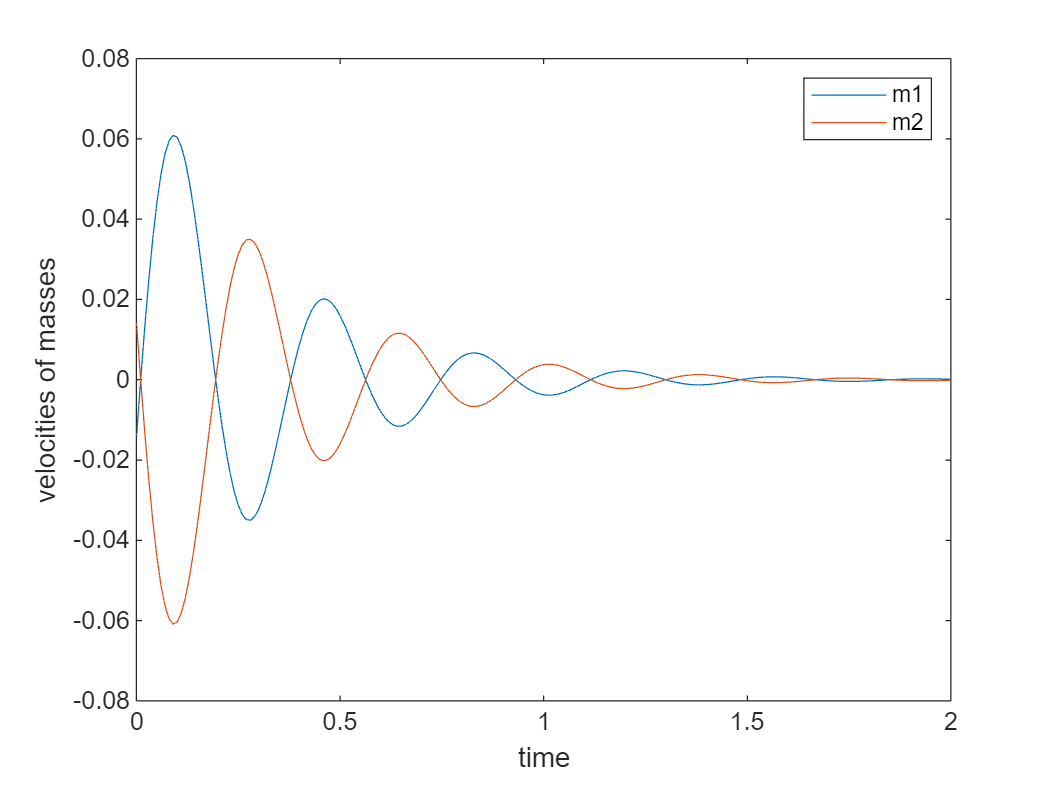

x0 = sum(v(:,1:2),2);
x0new = TR\x0; %same as TR^-1 * x0

%simulate the system with the new intial state vector 
t = (0:0.01:2)'; 
u = [0*t,0*t]; 
[ynew,tout] = lsim(dmsdSSmodal,u,t,x0new); 


plot(tout,ynew(:,[1,3]))
xlabel('time'); 
ylabel('velocities of masses'); 
legend('m1', 'm2')

## Insights from Modal representation

When the system is in mode 1, note that the velocities of the masses are always in opposite direction. This ensures that the momentum of the entire system always remains zero. This is a very useful property to have if we don't want the entire system to vibrate. Therefore, from a control design perspective, it makes sense for us to keep the system in mode 1. So, how can we do this? 

Oberve the new $B$ matrix 

dmsdSSmodal.B

**Reflect:**

- Observe the last two rows of the $B$ matrix. Based on your observation, if we apply equal and opposite forces on the masses, will there be any effect on the second mode? Explain your answer. 

**Enter your answer here:**